## Exercise 1

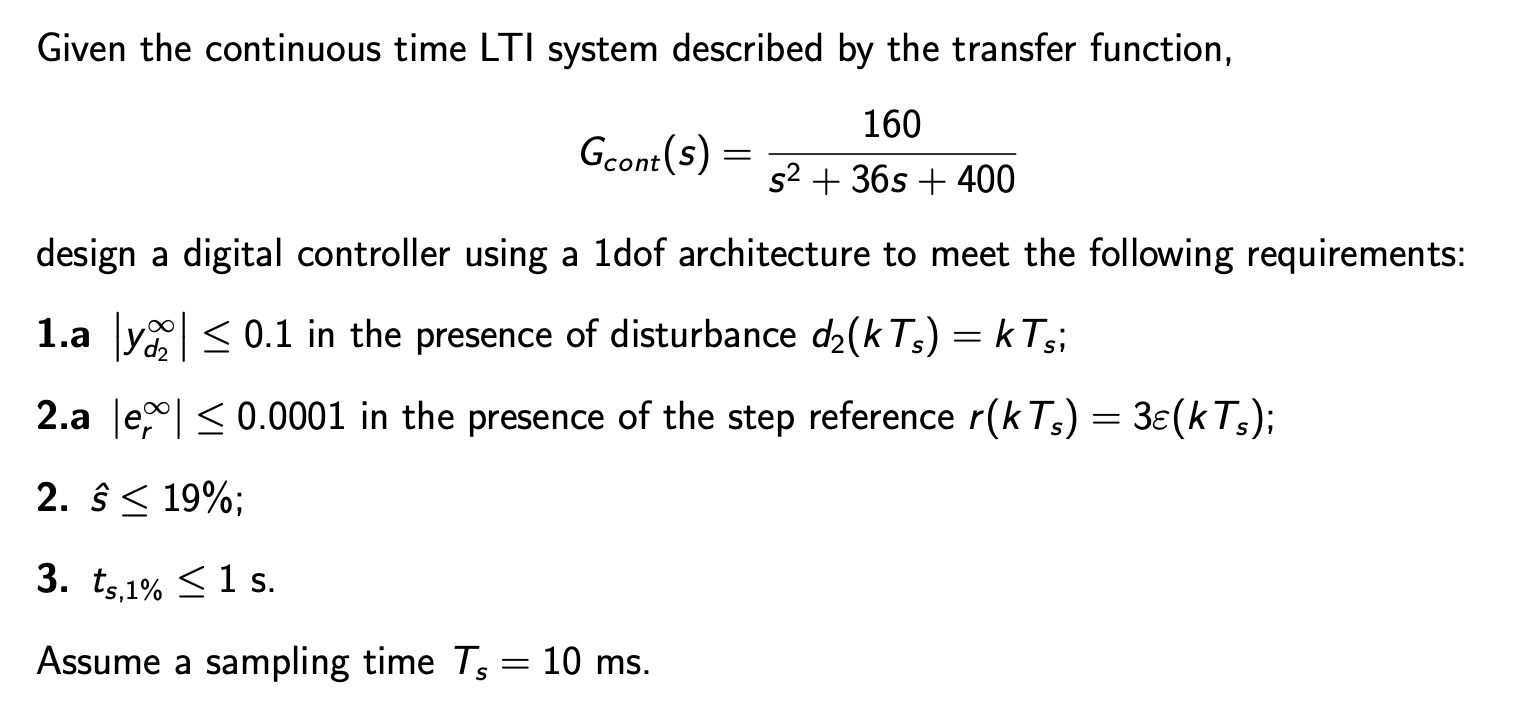

close all
clear
clc

s = tf('s');

Ts = 10e-3;
z = tf('z',Ts);

Gcont = 160/(s^2+36*s+400);

G = zpk(c2d(Gcont,Ts,'zoh'));


G =
 
   0.0070974 (z+0.8869)
  -----------------------
  (z^2 - 1.664z + 0.6977)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.



[zG, pG, kG] = zpkdata(G, 'v')

zG = -0.8869

pG =    0.8321 + 0.0727i
   0.8321 - 0.0727i


kG = 0.0071


A = conv([1 -pG(1)], [1 -pG(2)]);
B = kG*[1 -zG];

#### SS requirements

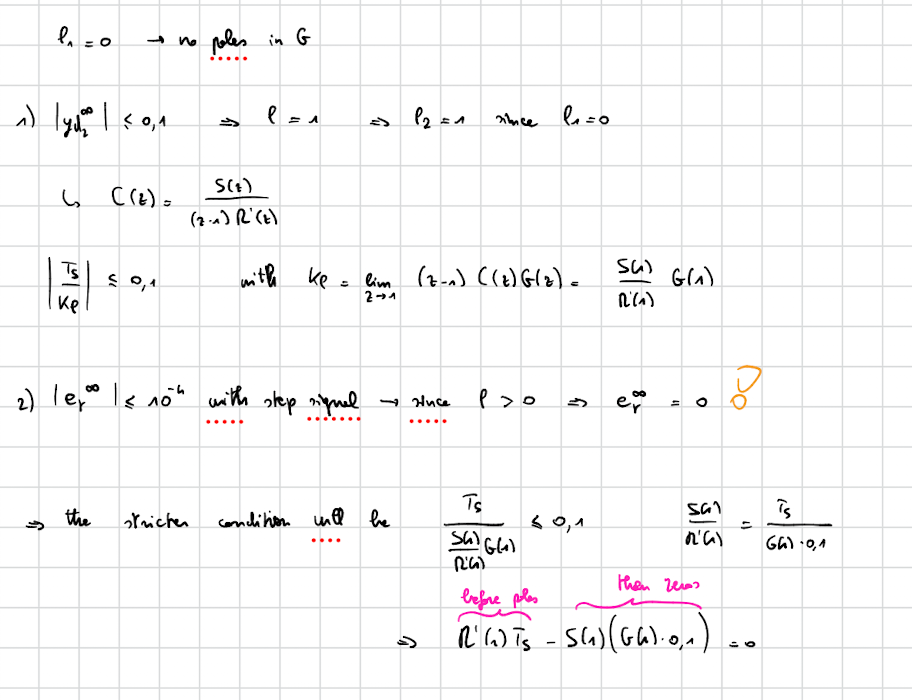

We will need a pole in 1 and an extra equation for Ms

l1 = 0;
l2 = 1;
l = l1+l2;
n_add = 1;

#### Transient response

s_hat = 0.19; % overshoot
t_s = 1; % setting time
zeta = abs(log(s_hat))/sqrt(pi^2+log(s_hat)^2); 
wn = 4.6/(zeta*t_s);  

% figure
% pzmap(G, 'r')
% hold on
% zgrid(zeta,wn, Ts)
% axis('equal')

From the plot we clearly see that we can cancel all the G poles

A_minus = 1;
A_plus = A;
B_minus = B;
B_plus = 1;

% degree
deg_A = 2;
deg_A_minus = 0;
deg_A_plus = 2;
deg_B_plus = 0;
deg_B_minus = 1;

deg_S1 = l + deg_A_minus - 1 + n_add

deg_S1 = 1

deg_R2 = deg_A - deg_B_plus + l1 - 1 + n_add

deg_R2 = 2

deg_Am = l + deg_A + deg_A_minus + l1 - deg_B_plus - 1 + n_add

deg_Am = 3

Since deg(Am) = 3 we'll choose 2 complex conj poles and a real one

p1c = -zeta*wn + 1j*wn*sqrt(1-zeta^2);
p1 = exp(p1c*Ts); % sampling transformation -> I get the pole value in DT
p2c = -zeta*wn - 1j*wn*sqrt(1-zeta^2);
p2 = exp(p2c*Ts); 

p3c = -5*zeta*wn; % this real pole is faster than p1 and p2
p3 = exp(p3c*Ts);

Am = poly([p1 p2 p3]);

Now we need to build the extra eq

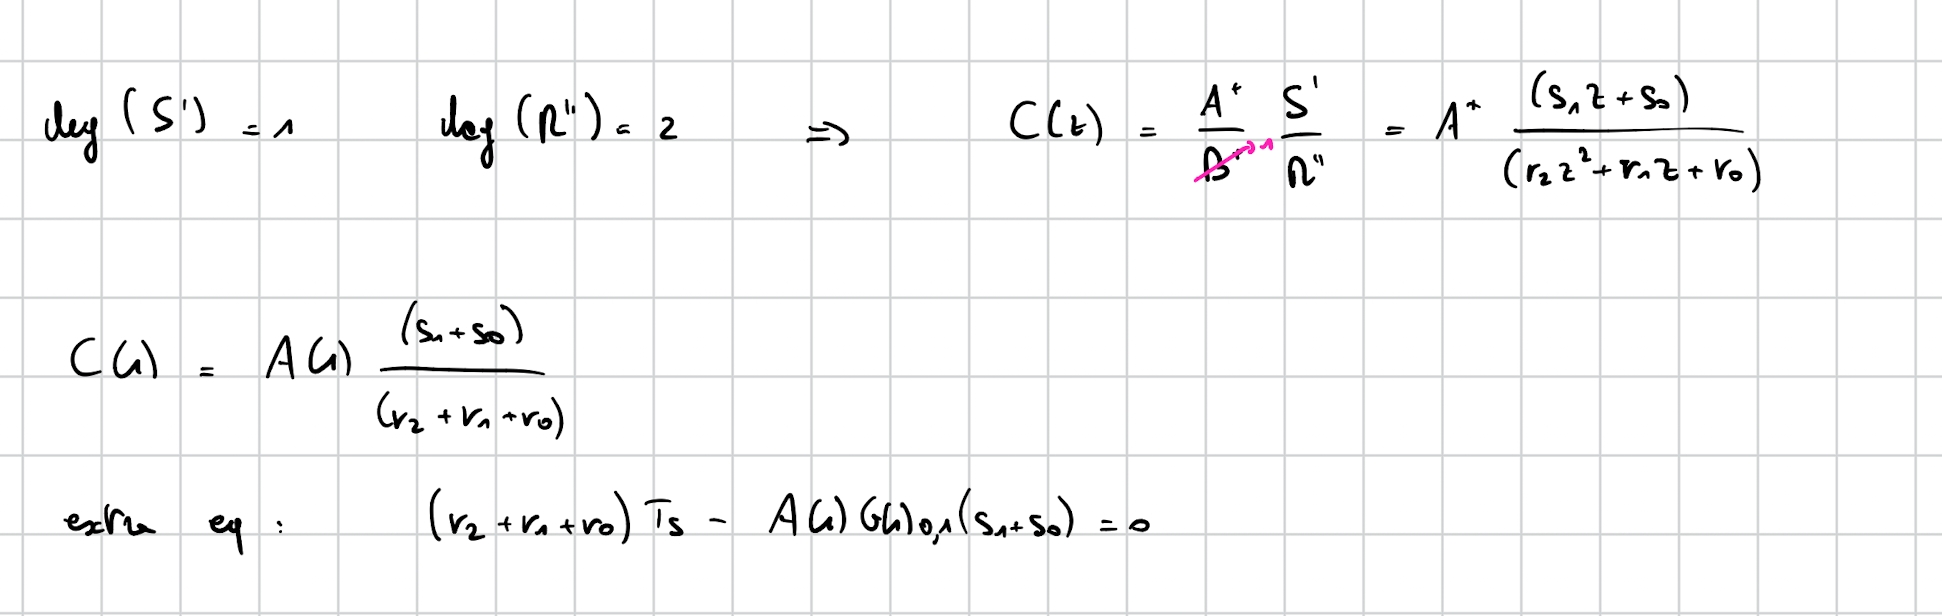

A_plus_1 = polyval(A_plus,1);
G_1 = dcgain(G);
extra_eq = [Ts*ones(1,3), -A_plus_1*G_1*0.1*ones(1,2)];

Let's now solve dioph eq

Adioph = [1 -1];
Bdioph = B;

[R2, S1, Ms] = diop_solver(Adioph,Bdioph,Am, deg_R2,n_add,extra_eq)

diop_solver is not found in the current folder or on the MATLAB path, but exists in:
    /Users/davidecovolo/Documents/MATLAB/Dictar/ExamplesAndLabs/LECTURE_EXAMPLES/1_DOF_lectures
    /Users/davidecovolo/Documents/MATLAB/Dictar/ExamplesAndLabs/HomemadeFunctions

Change the MATLAB current folder or add its folder to the MATLAB path.

Now let's build the controller

R = conv([1 -1], R2);
S = conv(A_plus, S1);
C = zpk(tf(S,R,Ts))

#### Simulations

Tend = 2;
G_ct = Gcont; % siccome le simulazioni hanno G_ct

Let's start from transient response and tracking error, by applying a step of amplitude 3 

rho = 3; % step amplitude
delta_1 = 0; % ignore these contributes 
delta_2 = 0; 
sim = sim("sim_with_disturbances.slx");
y = sim.y;
r = sim.r;
e = sim.e;

figure
plot(y.time, y.data, linewidth=1.5)
hold
plot(r.time, r.data, linewidth=1.5)
legend("risposta","ref")
title("response")

figure
plot(e.time, e.data, LineWidth=1.5)
title("tracking error")

From the plot we can see that both transient requirements are satisfied and that tracking error is asymptotically zero

Now let's verify yd2_inf

clear sim

rho = 0; % ignore this
delta_1 = 0;  
delta_2 = 1; 
sim = sim("sim_with_disturbances.slx");
y = sim.y;

figure
plot(y.time, y.data, linewidth=1.5)
title("y_{d2}_{inf}")
